Read images

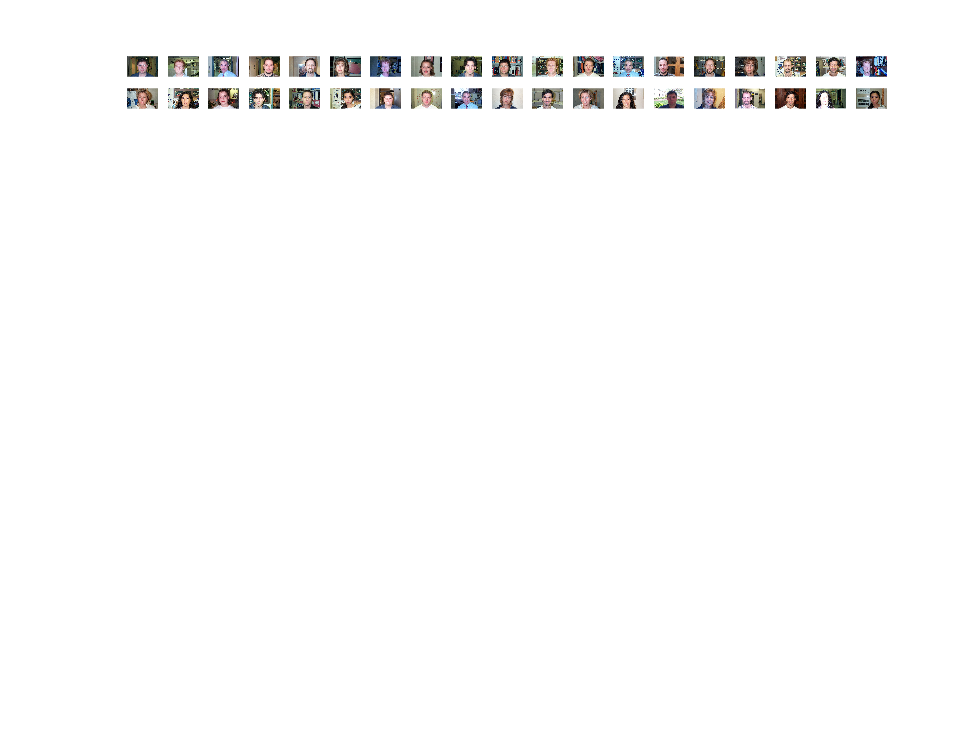

folder = "DB0"; %%locate folder
imagefiles = dir(fullfile(folder,'*.jpg')); %%store the images
nfiles = length(imagefiles); %%define number of images.
Im = cell(1,nfiles); %%Allocate space

%%for each image
for i = 1:nfiles
  filename=fullfile(folder,imagefiles(i).name); %%get filename of current image.
  subplot(nfiles/2, nfiles/2, i); %%define location to plot the image in our subplot.
  Im{i}=im2double(imread(filename)); %%Read the imagefile, convert to double and store it.
  imshow(Im{i}) %%Show the current image in a subplot.
end

Convert to YCbCr and create an eye map according to the *Face Detection in Color Images* paper.

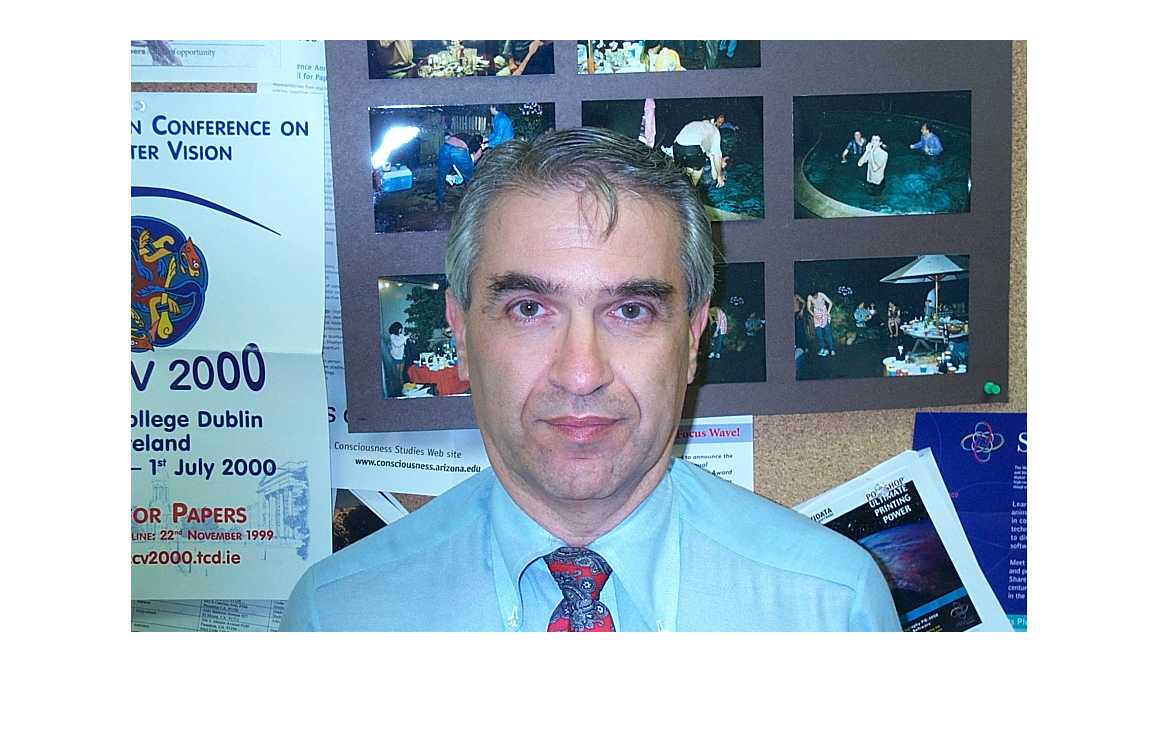

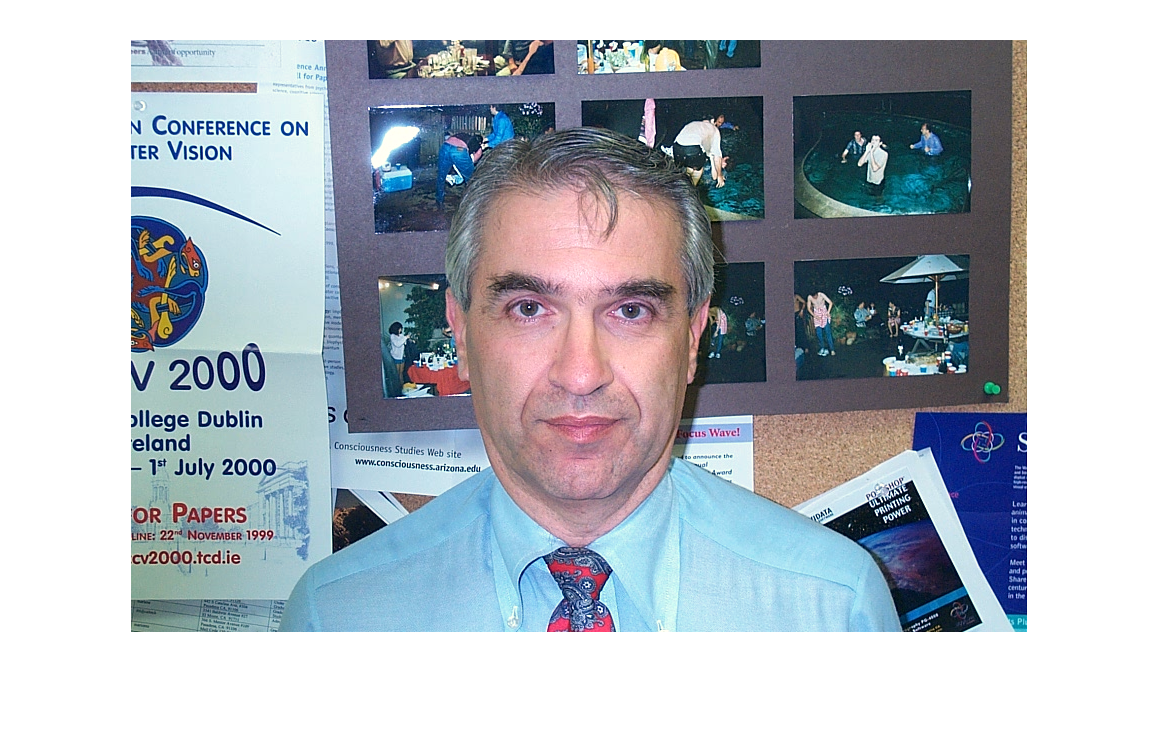

ans = ans(:,:,1) =

    0.6684    0.7215    0.7392    0.7437    0.7171    0.6950    0.6551    0.6773    0.7127    0.7259    0.7259    0.6684    0.5135    0.3763    0.3630    0.2700    0.3895    0.4294    0.4072    0.4604    0.5312    0.4382    0.3276    0.4781    0.6286    0.4869    0.3541    0.3718    0.4648    0.4913    0.6374    0.6950    0.7082    0.7437    0.7702    0.8145    0.7127    0.6507    0.6374    0.5622    0.5002    0.5312    0.6728    0.7746    0.8145    0.8189    0.7835    0.7614    0.7923    0.7835    0.7879    0.7968    0.7968    0.7879    0.7879    0.7923    0.7791    0.7835    0.7879    0.7658    0.7569    0.7923    0.8145    0.7879    0.8056    0.7791    0.7835    0.7923    0.7702    0.7746    0.8012    0.7746    0.7923    0.7835    0.7879    0.7923    0.7968    0.8012    0.7923    0.7879    0.8189    0.8189    0.8278    0.7791    0.8145    0.8101    0.7968    0.8101    0.8145    0.8145    0.8189    0.8101    0.8322    0.8189    0.8233    0.8322    0.8145    0.8278

%The following requires image processing toolbox.
currentImage = Im{4};
lighting_compensation(currentImage, 0.05)

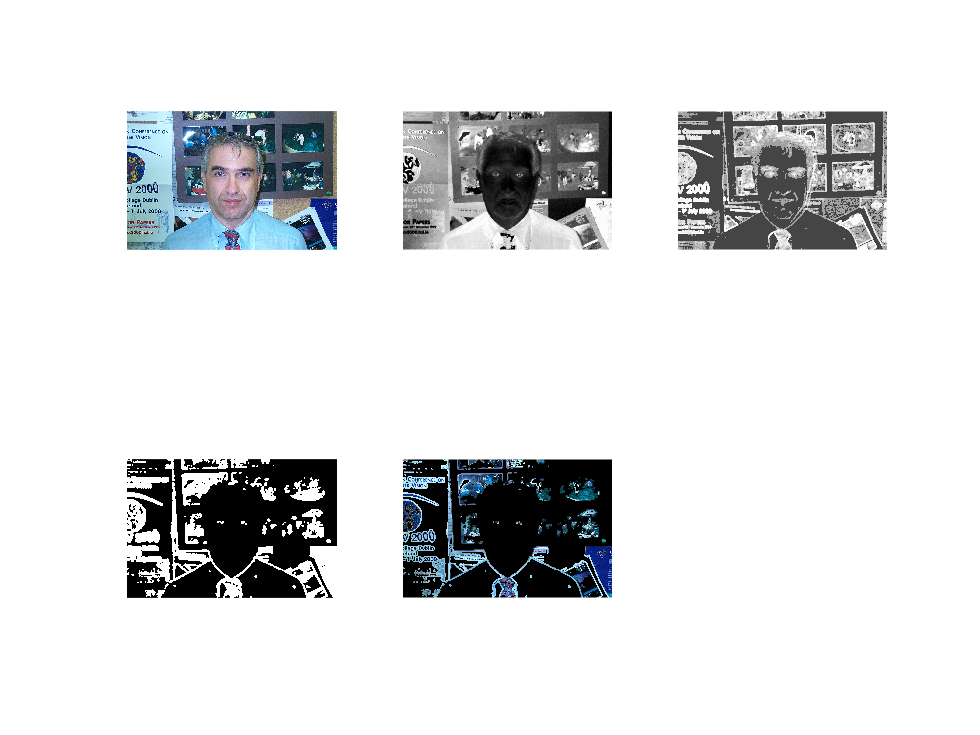

[chromaIm, lumaIm, EyeMap] = eye_detection(currentImage);

%%Create a figure and subplot the eye maps. 
figure;
subplot(2,3,1);
imshow(currentImage);
subplot(2,3,2);
imshow(chromaIm)
subplot(2,3,3);
imshow(lumaIm);
subplot(2,3,4);
imshow(EyeMap);
subplot(2,3,5);
imshow(EyeMap.*currentImage);

Mouth map

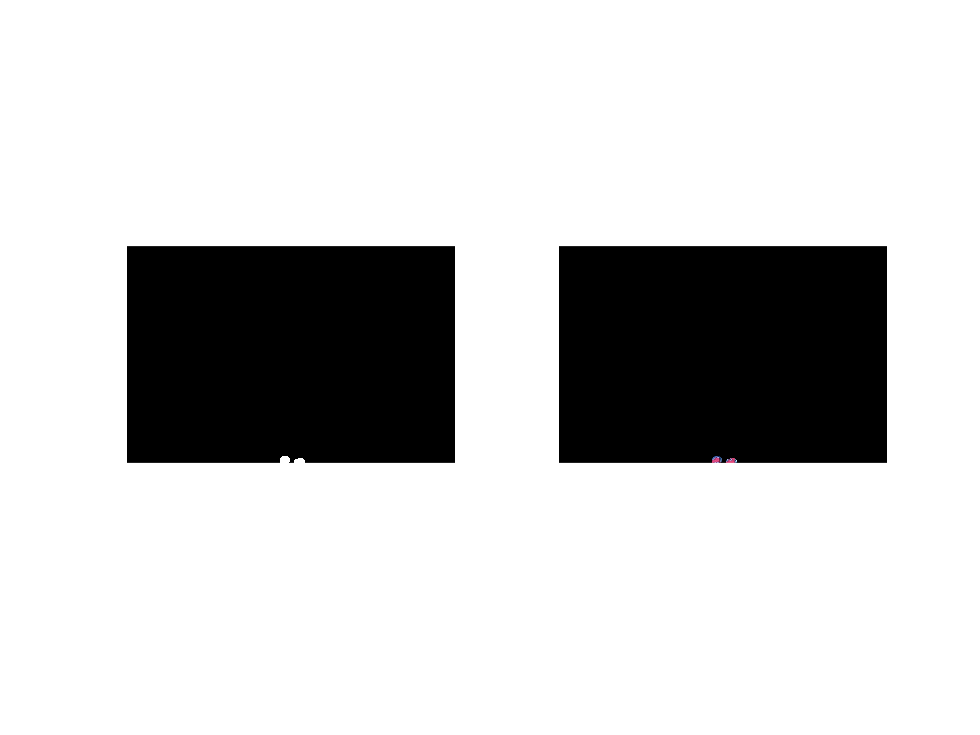

MouthMap = mouth_detection(currentImage);
figure;
subplot(1,2,1);
imshow(MouthMap);
subplot(1,2,2);
imshow(currentImage.*MouthMap);

Form an eye-mouth triangle.

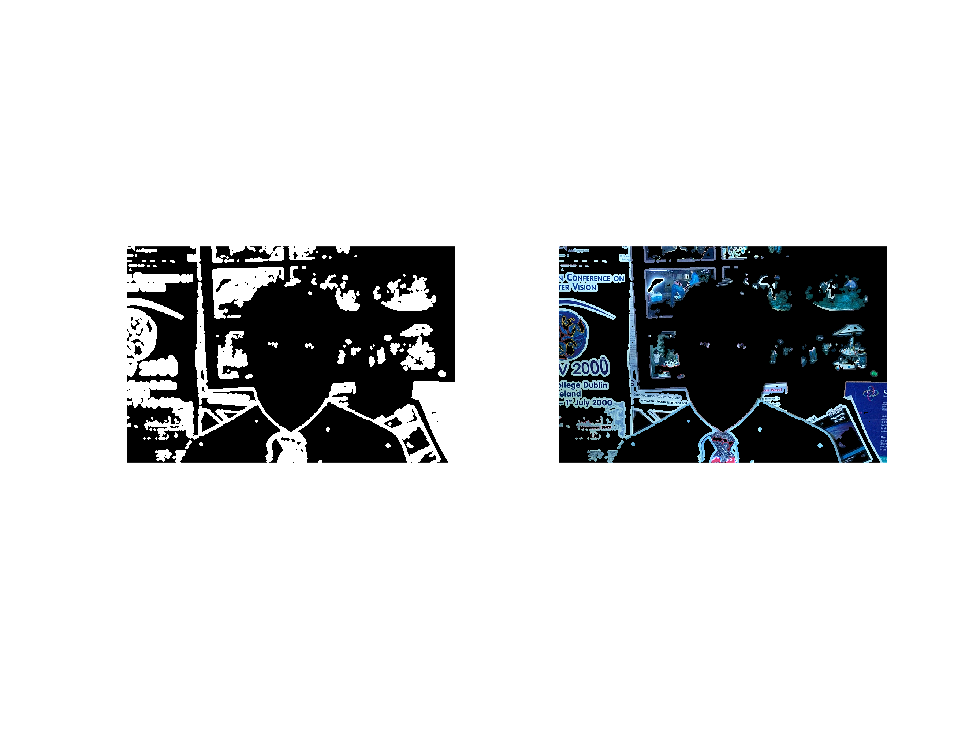

Triangle = EyeMap + MouthMap;
figure;
subplot(1,2,1);
imshow(Triangle);
subplot(1,2,2);
imshow(Triangle.*currentImage);